空域信息隐藏

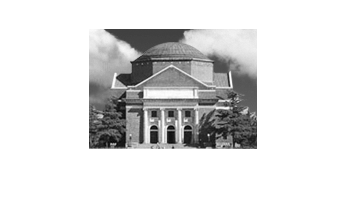

clear
clc

load('hall.mat');
[h, w] = size(hall_gray,[1 2]);
info = uint8(randi([0 1],h,w)); % 生成测试信息

imageConceal = bitset(hall_gray,1,info); % 空域隐藏
[ACstream, DCstream, h, w] = JpegEncoder(imageConceal);
ImageRslt = JpegDecoder(DCstream,ACstream,h,w);

infoRetrieve = bitget(ImageRslt,1); % 恢复信息

imshow(imageConceal);

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRetrieve); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

fidelity = 0.5005, 0.5011, 0.4953, 0.5004, 0.4936

与再随机生成一个还原后得结果计算还原率无异，几乎无法还原任何有用信息